# import .mff file (collected @LAND) and convert into .set format

check input parameters

clear all

hostname = char(getHostName(java.net.InetAddress.getLocalHost));

% ???
% option for downloading the file directly from ONEDRIVE:
% https://drive.matlab.com

## 1) PARAMETERs

% <<< TO SET <<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<
eeglab_dir = 'C:\Users\andrea.vitale\Desktop\_TOOLBOX\eeglab_20201226'
project_dir = 'C:\Users\andrea.vitale\Desktop\_PROJECT\CMI_EEG_HACKing_session'

data_dir = 'data_LAND_mff'
save_dir = 'data_LAND_set'

subj_id = 'D9rj73y989'
%subj_id = 'D9tj73y989'

%task_name = 'RS_inscapes'
%task_name = 'RS_cross'
task_name = 'RS_eyesclosed'

%session_numb = '02'
%session_numb = '03'
%session_numb = '04'  %????
session_numb = '05'  %????

do_save = 1;

% <<< TRIGGER TABLE <<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<
task = {'RS_cross';'RS_eyesclosed';'RS_inscapes'};
trigger_start = {'cros';'';'VidO'};
trigger_end = {'';'';' '};

trigger_table = table(task, trigger_start, trigger_end)
                  

## 2) check if the .mff folder exist and IMPORT

% DATA STRUCTURE temporary = = =  == =  = = = = = = = = = = = = = =
folder_name = [ subj_id '_' task_name '_' session_numb ]
%folder_path = fullfile(project_dir, data_dir, folder_name)

% DATA STRUCTURE def = = =  == =  = = = = = = = = = = = = = = = = =

% = = =  == =  = = = = = = = = = = = = = = = = =  == =  = = = = = = 

cd(fullfile(project_dir, data_dir))
folder_list = dir('*.mff')
%exist(folder_name, dir('*.mff'))
file_name = [];
for i_folder = 1:length(folder_list)
    %i_folder=
    if contains(folder_list(i_folder).name, folder_name)
        file_name = folder_list(i_folder).name
        % no mff extension
        file_name = file_name(1:end-4);
        disp('mff file EXIST !!')
    end
end
if isempty(file_name); disp('!!! mff file does NOT EXIST !!'); end

% use EEGLAB for loading the mff file 
cd(eeglab_dir)
eeglab%()

% LOAD - - - - - - 
eeg_struct = [];
try
    eeg_struct = pop_mffimport({fullfile(project_dir, data_dir, [file_name '.mff'])},{'code'});
catch error_message
    disp(error_message)
    if ~isempty(ME)
        % that means there are some problems with the triggers:
        % NO EVENTs in the data file
        eeg_struct = pop_mffimport({fullfile(project_dir, data_dir, [file_name '.mff'])});
    end
end


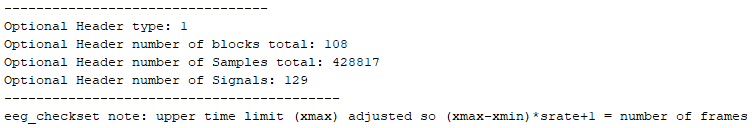

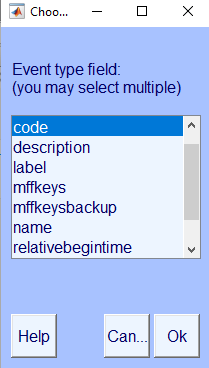

## 3) check if CHANNEL LAYOUT is correctly imported

figure; 
topoplot([], eeg_struct.chanlocs, 'style', 'blank',  'electrodes', 'labelpoint', 'chaninfo', ...
             eeg_struct.chaninfo);

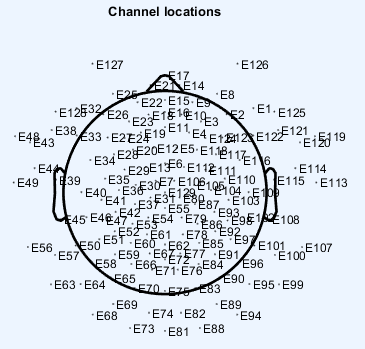

E127 and E128 should be the most frontal sensors

E81  = 'Iz'

%% check EVENT structure
eeg_struct.event
eeg_struct.xmax
         

## 4) remove empty portion of the data (if present)

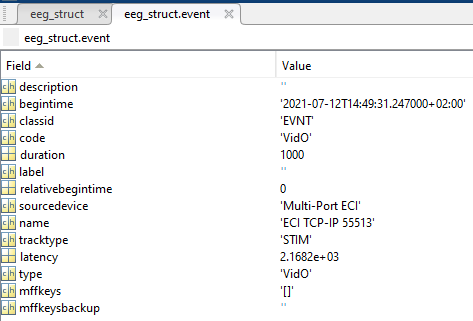

% the VidO event corresponds to the onset of the video
% so we can remove the initial part of the recording until the latency value (in sample ?)

%EEG =eeg_struct; eeglab redraw

% find sample corresponding to trigger_start
time_vector_msec = eeg_struct.times;

%find(strfind(task_name, trigger_table))
[~, task_idx] = ismember(task_name, trigger_table.task)

n_event = length(eeg_struct.event)
%event_name = {}; event_latency = [];
event_start_msec = []; event_stop_msec = [];
event_start_sampleidx = []; event_stop_sampleidx = [];
for i_event = 1:n_event
    if strcmp(eeg_struct(i_event).event.code, trigger_table.trigger_start{task_idx})
        event_start_msec = eeg_struct(i_event).event.latency
        %event_name{i_event,1} = eeg_struct(i_event).event.code;
        %event_latency[i_event,1] = eeg_struct(i_event).event.latency;
    
        [ ~, event_start_sampleidx ] = min(abs(time_vector_msec - event_start_msec))

    elseif strcmp(eeg_struct(i_event).event.code, trigger_table.trigger_start{task_idx})
        event_stop_msec = eeg_struct(i_event).event.latency
        [ ~, event_stop_sampleidx ] = min(abs(time_vector_msec - event_stop_msec))

    end    
end

if isempty(event_start_sampleidx)
    event_start_sampleidx = 1
end
if isempty(event_stop_sampleidx)
    event_stop_sampleidx = length(time_vector_msec) -1
end

eeg_struct = pop_select( eeg_struct, 'point',[event_start_sampleidx-1  event_stop_sampleidx+1] );

by cutting the initial portion of the recording 

the trigger onset appears exactly at the first sample of the new data file

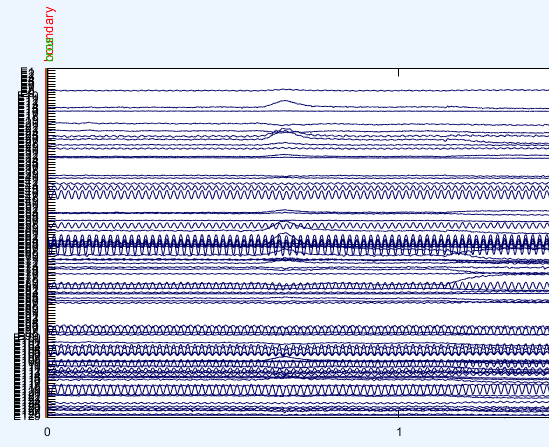

## 5) and SAVE in .set format

if do_save
    eeg_struct = pop_saveset( eeg_struct, 'filename', [file_name '.set'], ...
         'filepath', fullfile(project_dir, save_dir))
                      %'C:\\Users\\andrea.vitale\\Desktop\\_PROJECT\\CMI_EEG_HACKing_session\\data_LAND_set\\');
end


% cfg = [];
% cfg.dataset     = 'dataset_name';
% cfg.channel     = {'EEG'};
% 
% cfg.dftfilter  = 'yes';
% cfg.dftfreq    = [60 120 180];
% 
% %or
% %cfg.bpfilter    = 'yes';
% %cfg.bpfreq      = [58 62; 118 122];
% 
% data_notch      = ft_preprocessing(cfg);